# Last factor optimization   

To test if a reduced design matrix (RDM) $(r \times n)$ is rL-minimal, we have to check all possible:

- Row permutations

- Column permutations

- Possible set of new basic factors

To see if any, produces a design that is rL-smaller.

A possible set of new basic factors, is a set of $r$ columns among the $n$, which are linearly independent of each other. To test if a set is linearly independent, we compute the reciprocal condition inversion number.

However, another condition might be interesting, is that the new set of basic factor must contain the last factor added to the parent design, because if it doesn't, it means that the combination has already been tested previously.

Therefore, we could restrict the search for new sets of basic factors, to sets that:

- Are linearly independent

- Contain the last added factor.

This reports test if optimizing the algorithm, by implementing this restriction, yields any advantage in terms of computing time.

## Methodology

To test this restriction, we tested all pemutations of a given design and tested if:

- The new set of basic factors contained the last added factor

- The new set of basic factors is linearly independent

- The produced design is rL-smaller

And compiled into a single vector, which, for a single design gives us:

- True if it is rL-smaller

- Number of discarded new sets of basic factors

- Number of iterations needed to find the rL-smaller design

The goal is now to compare if these values are more advantageous when we use the last-factor optimization method (LFopt).

load('16RunCatalog.mat');
nmin = 5;
nmax = 14;
Rmat = [];
Imat = [];
for n = nmin:nmax
    colsMat = cell2mat(T(T.n == n,:).cols);
    nd = size(colsMat,1);
    resMat = zeros(nd*15,8);
    for ii = 1:size(colsMat,1)
        cols = colsMat(ii,:);
        for jj = 1:15
            if ismember(jj,cols)
                continue
            end
            index = (ii-1)+jj;
            [rL, discR, noLFR, totR, numIt] = LastFacOptrLmin([cols jj],true);
            resMat(index,:) = [n ii jj rL discR noLFR totR, numIt];
        end
    end
    resMat = resMat(any(resMat,2),1:end); % Keep non-zero rows
    Rmat = [Rmat; resMat(:,1:end-1)];
    Imat = [Imat; resMat(:,[1 4 8])];
end

### New sets of basic factors

Given a design with $n$ factors, there are $\left(\begin{array}{c}
n\\
r
\end{array}\right)$ ways of picking a set of new basic factors. However, using LFopt, there are only $\left(\begin{array}{c}
n-1\\
r-1
\end{array}\right)$.

The following graphs shows us, for each possible number of factors, the average percentage of new sets of basic factors which:

- Are discarded because they are linearly dependent

- Are discarded because they do not contain the last factor

- Are kept for further analysis

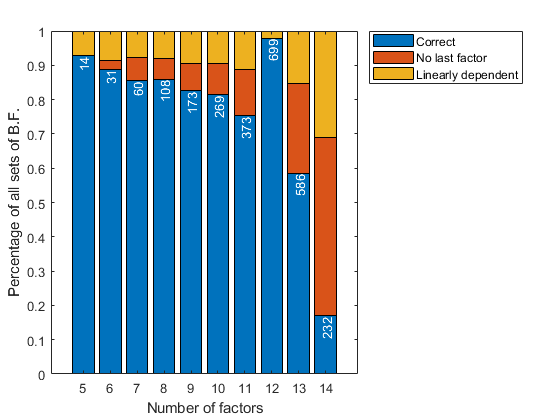

meanRmat = zeros(nmax-nmin,4);
labels = zeros(1,nmax-nmin);
for n = nmin:nmax
    subR = Rmat(Rmat(:,1)==n,:);
    labels(n-nmin+1) = mean(subR(:,7)-subR(:,6)-subR(:,5));
    meanRmat(n-nmin+1,1:end-1) = [n mean(subR(:,5)./subR(:,7)) mean(subR(:,6)./subR(:,7))];
    meanRmat(n-nmin+1,end) = 1 - meanRmat(n-nmin+1,2) - meanRmat(n-nmin+1,3);
end
figure 
b = bar(meanRmat(:,1),meanRmat(:,4:-1:2),'stacked');
legend({'Correct','No last factor','Linearly dependent'},'Location','bestoutside');
xlabel('Number of factors');
ylabel('Percentage of all sets of B.F.');
xtips = nmin:nmax;
ytips = b(1).YEndPoints;
labels = string(round(labels));
text(xtips,ytips,labels,'HorizontalAlignment','right','VerticalAlignment','middle','Rotation',90,'Color',[1 1 1])

We see that the biggest difference that the LFopt makes, is when there is a large number of factor. This is convenient since the number of sets to test is proportional to $n$. This proves that the LFopt will yield large time gains for designs with a lot of factors.

### Number of iterations

We've seen that the LFopt decreases the number of new set of designs to test. We will now check if, among those remaining sets, the number of iterations needed to obtain an rL-smaller design (if such design exists), is lower using the LFopt algorithm.

To check, we computed the maximal number of iteration needed to reach the rL-smaller design as $\left(\begin{array}{c}
n\\
r
\end{array}\right)\times r!$ when using the normal algorithm and as $\left(\begin{array}{c}
n-1\\
r-1
\end{array}\right)\times r!$ when using the LFopt algorithm. Then we simply computed the percentage of that maximum, that was actually needed to reach the rL-smaller design.

meanImat = zeros(nmax-nmin,3);
for n = nmin:nmax
    index = n-nmin+1;
    subI = Imat(Imat(:,1)==n,:);
    tot = nchoosek(n-1,3)*factorial(4); 
    meanImat(index,:) = [n round(mean(subI(:,3))) tot];
end
T = array2table(meanImat,"VariableNames",{'n','Average number of iterations needed','Max number of iterations possible'})

T = 10×3 table
    n     Average number of iterations needed    Max number of iterations possible
    __    ___________________________________    _________________________________

     5                     18                                    96               
     6                     44                                   240               
     7                    113                                   480               
     8                    154                                   840               
     9                    218                                  1344               
    10                    365                                  2016               
    11                    816                                  2880               
    12                    187                                  3960               
    13                   2125                       

It is clear, from the table, that even though the theoretical number of iterations needed to reach the rL-smaller design is small, the actual average number of iterations is lower.  